load("C:\Users\Admin\Documents\JHU\Data Sets\Drive Folder\25-09-03(MilMed-2)-BS\Ephys recordings\Rec_1_unpacked.mat", 'unpackedFile');

Plotting each channel (0 to 3) on separate graphs as follows

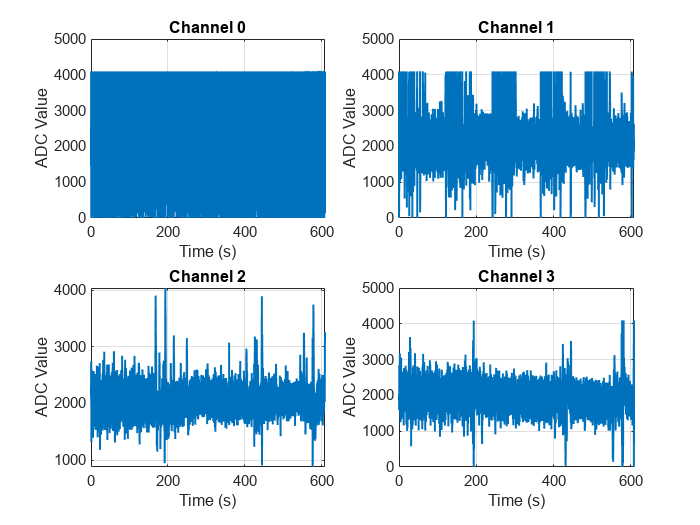

numChannels = size(unpackedFile.channelsData, 1);
totalSamples = size(unpackedFile.channelsData, 2);

figure;
for ch = 1:numChannels
    subplot(2,2,ch); % 2 rows x 2 columns
    plot(unpackedFile.time(1:totalSamples), unpackedFile.channelsData(ch,1:totalSamples), 'LineWidth',1.2);
    xlabel('Time (s)');
    ylabel('ADC Value');
    title(['Channel ' num2str(ch-1)]);
    grid on;
end

drawnow;

Each channel will show data as follows

CH0 - Left ear

CH1 - Scalp / Forehead

CH2 - Wrist of the left arm

CH3 - Ground

The signals need to be synchornized as they may have small difference in starting times between them. Here I have considered channel 0 as the reference.

ref = unpackedFile.channelsData(1, :); % CH0 as reference
fs = 10000;
numCompare = numChannels - 1;       % CH1 to CH3
numPlots = numCompare * 2;          % cross-corr + aligned signals per channel
rows = ceil(numPlots / 2);          % 2 columns

figure('Name','Cross-correlation & Aligned Signals');

plotIndex = 1;

alignedChannels = zeros(size(unpackedFile.channelsData)); % preallocate
alignedChannels(1,:) = ref;  % CH0 remains reference

for ch = 2:numChannels  % CH1, CH2, CH3
    test = unpackedFile.channelsData(ch, :);

    % Compute cross-correlation
    [Rxy, lags] = xcorr(test, ref);

    % 2b. Find best shift (k*)
    [~, idx] = max(Rxy);
    k_star = lags(idx);
    time_delay = k_star / fs; % in seconds

    fprintf('CH%d vs CH0: Lag = %d samples (%.6f s)\n', ch-1, k_star, time_delay);

    % Cross-correlation subplot
    subplot(rows, 2, plotIndex);
    plot(lags/fs, Rxy, 'LineWidth', 1.5); % x-axis in seconds
    xlabel('Lag (s)');
    ylabel('Cross-correlation');
    title(['CH' num2str(ch-1) ' vs CH0']);
    grid on;
    plotIndex = plotIndex + 1;

    % Align signals based on k*
    if k_star > 0
        test_aligned = test(1 + k_star:end);
        ref_aligned = ref(1:length(test_aligned));
    elseif k_star < 0
        ref_aligned = ref(1 - k_star:end);
        test_aligned = test(1:length(ref_aligned));
    else
        test_aligned = test;
        ref_aligned = ref;
    end

    % Save aligned channel
    alignedChannels(ch, 1:length(test_aligned)) = test_aligned;

    
    subplot(rows, 2, plotIndex);
    plot(unpackedFile.time(1:length(ref_aligned)), ref_aligned, 'LineWidth', 1.2); hold on;
    plot(unpackedFile.time(1:length(test_aligned)), test_aligned, 'LineWidth', 1.2);
    legend('Reference (CH0)', ['Aligned CH' num2str(ch-1)]);
    title(['Aligned Signals (all samples): CH' num2str(ch-1)]);
    xlabel('Time (s)');
    ylabel('ADC Value');
    grid on;
    plotIndex = plotIndex + 1;
  

end

CH1 vs CH0: Lag = 1300 samples (0.130000 s)
CH2 vs CH0: Lag = 15 samples (0.001500 s)
CH3 vs CH0: Lag = 736 samples (0.073600 s)


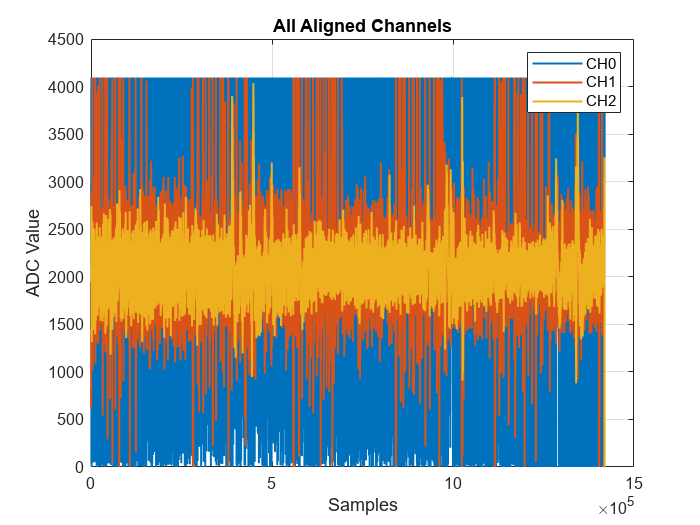

drawnow;

figure;
plot(alignedChannels(1,:), 'LineWidth', 1.2); hold on;
plot(alignedChannels(2,:), 'LineWidth', 1.2);
plot(alignedChannels(3,:), 'LineWidth', 1.2);
legend('CH0', 'CH1', 'CH2');
xlabel('Samples');
ylabel('ADC Value');
title('All Aligned Channels');
grid on;

% Assign aligned channels to separate variables
CH0 = alignedChannels(1, :);  % Left ear
CH1 = alignedChannels(2, :);  % Scalp / Forehead
CH2 = alignedChannels(3, :);  % Wrist
CH3 = alignedChannels(4, :);  % Ground

% Time vector for plotting
alignedTime = unpackedFile.time(1:length(CH0));
drawnow;

Now we remove the DC shift of each channel signal

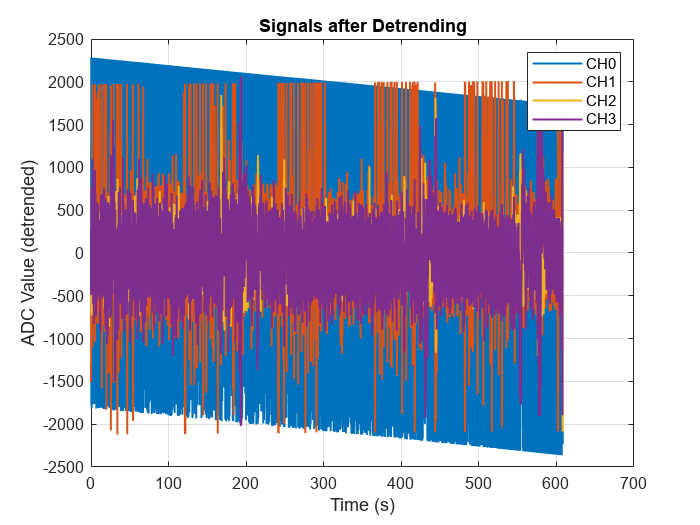

CH0_d = detrend(CH0);
CH1_d = detrend(CH1);
CH2_d = detrend(CH2);
CH3_d = detrend(CH3);

% Plot after detrending
figure;
plot(alignedTime, CH0_d, 'LineWidth', 1.2); hold on;
plot(alignedTime, CH1_d, 'LineWidth', 1.2);
plot(alignedTime, CH2_d, 'LineWidth', 1.2);
plot(alignedTime, CH3_d, 'LineWidth', 1.2);

legend('CH0', 'CH1', 'CH2', 'CH3');
xlabel('Time (s)');
ylabel('ADC Value (detrended)');
title('Signals after Detrending');
grid on;

drawnow;

Next we find the fft of each signal to check whether electromgneitc powerline noise is affected. If not we are good to proceed with.

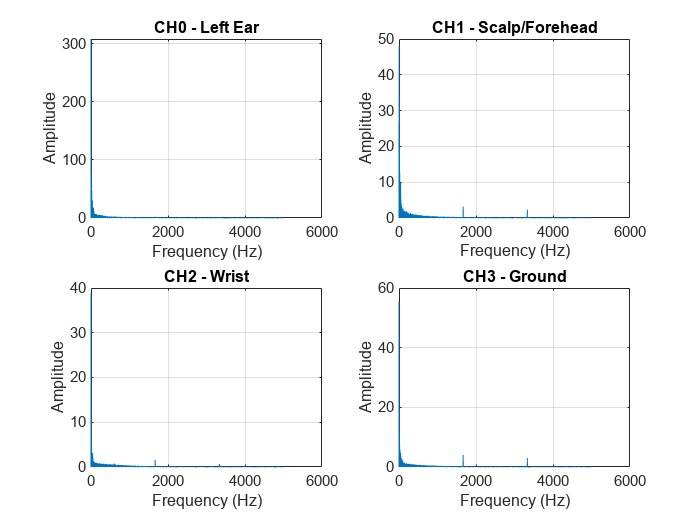

% Sampling frequency
fs = 10000; 

% Length of signal
N = length(CH0_d);

% Frequency vector for single-sided spectrum
f = (0:N-1)*(fs/N);
half_N = ceil(N/2);
f_single = f(1:half_N);

% Compute FFT
FFT_CH0 = fft(CH0_d);
FFT_CH1 = fft(CH1_d);
FFT_CH2 = fft(CH2_d);
FFT_CH3 = fft(CH3_d);

% Single-sided amplitude spectrum
amp_CH0_single = 2*abs(FFT_CH0(1:half_N))/N;
amp_CH1_single = 2*abs(FFT_CH1(1:half_N))/N;
amp_CH2_single = 2*abs(FFT_CH2(1:half_N))/N;
amp_CH3_single = 2*abs(FFT_CH3(1:half_N))/N;

% Plot
figure;
subplot(2,2,1); plot(f_single, amp_CH0_single); title('CH0 - Left Ear'); xlabel('Frequency (Hz)'); ylabel('Amplitude'); grid on;
subplot(2,2,2); plot(f_single, amp_CH1_single); title('CH1 - Scalp/Forehead'); xlabel('Frequency (Hz)'); ylabel('Amplitude'); grid on;
subplot(2,2,3); plot(f_single, amp_CH2_single); title('CH2 - Wrist'); xlabel('Frequency (Hz)'); ylabel('Amplitude'); grid on;
subplot(2,2,4); plot(f_single, amp_CH3_single); title('CH3 - Ground'); xlabel('Frequency (Hz)'); ylabel('Amplitude'); grid on;

drawnow;

Since we cannot find any 50Hz powerline noise or electromagnetic noise but we will be using the notch filter to cutoff 50 Hz.

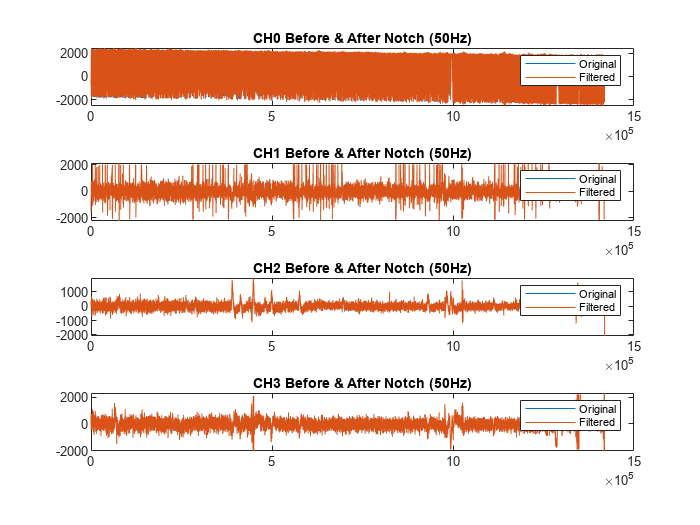

% Define mains frequency and sampling rate
fs = 10000;        % sampling frequency (Hz)
f0 = 50;           % notch frequency (Hz)
Q = 30;            % quality factor (controls sharpness of the notch)

% Design notch filter
wo = f0/(fs/2);    
bw = wo/Q;         
[b, a] = iirnotch(wo, bw);

% Apply notch filter to each channel
CH0_notched = filtfilt(b, a, CH0_d);
CH1_notched = filtfilt(b, a, CH1_d);
CH2_notched = filtfilt(b, a, CH2_d);
CH3_notched = filtfilt(b, a, CH3_d);

% Plot before and after filtering (optional visualization)
figure;
subplot(4,1,1);
plot(CH0_d); hold on; plot(CH0_notched); title('CH0 Before & After Notch (50Hz)');
legend('Original','Filtered');

subplot(4,1,2);
plot(CH1_d); hold on; plot(CH1_notched); title('CH1 Before & After Notch (50Hz)');
legend('Original','Filtered');

subplot(4,1,3);
plot(CH2_d); hold on; plot(CH2_notched); title('CH2 Before & After Notch (50Hz)');
legend('Original','Filtered');

subplot(4,1,4);
plot(CH3_d); hold on; plot(CH3_notched); title('CH3 Before & After Notch (50Hz)');
legend('Original','Filtered');


drawnow;

Now willl be implementing the 40Hz low pass filter.

% Sampling frequency
fs = 10000;   

% Design 50 Hz Notch Filter
wo = 50 / (fs/2);      % Normalized notch frequency
bw = wo / 35;          % Bandwidth
[b, a] = iirnotch(wo, bw);

% Design 1–40 Hz Hamming Band-Pass Filter (Order 100)
bpFilt = designfilt('bandpassfir', ...
    'FilterOrder', 100, ...
    'CutoffFrequency1', 1, ...
    'CutoffFrequency2', 40, ...
    'SampleRate', fs, ...
    'Window', 'hamming');

% Apply Filters
% Notch only
CH0_notched = filtfilt(b, a, CH0_d);
CH1_notched = filtfilt(b, a, CH1_d);
CH2_notched = filtfilt(b, a, CH2_d);
CH3_notched = filtfilt(b, a, CH3_d);

% Notch + Band-Pass

[b_bp, a_bp] = tf(bpFilt);  % Convert designfilt to filter coefficients

% Apply Filters correctly
CH0_filt = filtfilt(b_bp, a_bp, CH0_notched);
CH1_filt = filtfilt(b_bp, a_bp, CH1_notched);
CH2_filt = filtfilt(b_bp, a_bp, CH2_notched);
CH3_filt = filtfilt(b_bp, a_bp, CH3_notched);

t = (0:length(CH0_d)-1) / fs;

% Collect your signals in arrays
CH_notched = {CH0_notched, CH1_notched, CH2_notched, CH3_notched};
CH_filt    = {CH0_filt,    CH1_filt,    CH2_filt,    CH3_filt};
colors     = {[0 0 0], [0 0 1], [1 0 0], [1 0 1]};  % k, b, r, m
titles     = {'CH0', 'CH1', 'CH2', 'CH3'};

figure('Name','Notched vs Band-pass-Filtered Signals','NumberTitle','off');
set(gcf, 'Color', 'w');

for ch = 1:4
    subplot(2,2,ch)
    plot(t, CH_notched{ch}, 'Color', [0.6 0.6 0.6], 'LineWidth', 0.8); hold on
    plot(t, CH_filt{ch}, 'Color', colors{ch}, 'LineWidth', 1.2);
    title(titles{ch}); xlabel('Time (s)'); ylabel('Amplitude (V)');
    legend('Notch Only','Band-Pass + Notch','Location','best');
    grid on; axis tight; drawnow;
end

sgtitle('EEG/EMG Channels: 50 Hz Notch vs 1–40 Hz Band-Pass + Notch','FontWeight','bold');


Next it is a great leap for the signal quality validation on how to actually measure whether actual data is there or is it some random noise

Our goal is to increase the SNR of each and every signal so we use the ASR method to find the SNR value and will compare it with the RMS method.

Though the RMS method is accurate it does not measure the artifacts within the band of 0.5 - 40 Hz but the ASR method does.

% Pack channels into matrix (channels x samples)
CH0_notched = CH0_notched(:)'; 
CH1_notched = CH1_notched(:)'; 
CH2_notched = CH2_notched(:)'; 
CH3_notched = CH3_notched(:)'; 

data = double([CH0_notched; CH1_notched; CH2_notched; CH3_notched]);
[numCh, N] = size(data);

if ~exist('fs','var')
    error('Please define fs (sampling rate) before running this script, e.g. fs = 10000;');
end

% ------------------------------
% RMS-based SNR (simple method)
SNR_rms_db = zeros(numCh,1);
for ch = 1:numCh
    x = data(ch,:);
    % estimate 'noise' as deviation from median-smoothed signal
    med_win_s = 0.2; % 200 ms window
    medS = max(1, round(med_win_s * fs));
    baseline = medfilt1(x, medS);
    noise_est = x - baseline;
    % RMS SNR
    rms_sig = sqrt(mean(x.^2));
    rms_noise = sqrt(mean(noise_est.^2));
    SNR_rms_db(ch) = 20*log10( (rms_sig + eps) / (rms_noise + eps) );
end

fprintf('\n=== RMS SNR (dB) ===\n');


=== RMS SNR (dB) ===


for ch=1:numCh
    fprintf('CH%d RMS SNR = %.2f dB\n', ch-1, SNR_rms_db(ch));
end

CH0 RMS SNR = 0.50 dB
CH1 RMS SNR = 1.89 dB
CH2 RMS SNR = 5.42 dB
CH3 RMS SNR = 4.07 dB


% ASR-based SNR (simplified)
fs_small = 250;    % downsample for ASR
win_sec = 0.5;     % ASR window
overlap_frac = 0.5;
k = 5;             % burst criterion

% Downsample
p = fs_small; q = fs;
data_ds = zeros(numCh, ceil(N * fs_small / fs));
for ch=1:numCh
    data_ds(ch,:) = resample(data(ch,:), p, q);
end
fs_proc = fs_small;
Nds = size(data_ds,2);

% Select calibration (low variance)
cal_epoch_sec = 1.0;
epochS = round(cal_epoch_sec * fs_proc);
nEpochs = floor(Nds / epochS);
epochVar = zeros(nEpochs,1);
for e=1:nEpochs
    idx = (e-1)*epochS+1 : e*epochS;
    epochVar(e) = mean(var(data_ds(:, idx),0,2));
end
medv = median(epochVar);
sel = find(epochVar <= 1.5*medv);
cal_idx = [];
for s = sel(:)'
    cal_idx = [cal_idx, (s-1)*epochS+1 : s*epochS];
end
cal_idx = unique(min(max(cal_idx,1),Nds));
Xcal = data_ds(:, cal_idx);

% Whitening
Cref = cov(Xcal.');
[Vref, Dref] = eig(Cref);
eigvals_ref = diag(Dref); eigvals_ref(eigvals_ref<eps)=eps;
Lambda_inv_sqrt = diag(1./sqrt(eigvals_ref));
W = Lambda_inv_sqrt * Vref';
Winv = Vref * diag(sqrt(eigvals_ref));

% Sliding-window ASR SNR
winS = max(2, round(win_sec * fs_proc));
hop = max(1, round(winS*(1-overlap_frac)));
clean_ds = zeros(size(data_ds));
weight = zeros(1, Nds);
hann_win = hann(winS)';

for start = 1:hop:(Nds-winS+1)
    idx = start:(start+winS-1);
    Xw = data_ds(:, idx);
    Zw = W*Xw;
    Cw = (Zw*Zw') / (size(Zw,2)-1);
    [Vw, Dw] = eig(Cw);
    lamb = max(diag(Dw), eps);
    gamma = min(1, k./sqrt(lamb));
    Pw = Vw*diag(gamma)*Vw';
    Xw_clean = Winv * Pw * W * Xw;
    clean_ds(:, idx) = clean_ds(:, idx) + (Xw_clean .* hann_win);
    weight(idx) = weight(idx) + hann_win;
end
nz = weight>0;
clean_ds(:, nz) = clean_ds(:, nz) ./ weight(nz);
zero_idx = find(weight==0);
if ~isempty(zero_idx), clean_ds(:,zero_idx)=data_ds(:,zero_idx); end

% ASR SNR computation
residual_ds = data_ds - clean_ds;
SNR_asr_db = zeros(numCh,1);
for ch=1:numCh
    var_clean = var(clean_ds(ch,:));
    var_res = var(residual_ds(ch,:)) + eps;
    SNR_asr_db(ch) = 10*log10(var_clean/var_res);
end
for ch=1:numCh
    fprintf('CH%d ASR SNR = %.2f dB\n', ch-0, SNR_asr_db(ch));
end

CH1 ASR SNR = 29.48 dB
CH2 ASR SNR = 34.47 dB
CH3 ASR SNR = 15.66 dB
CH4 ASR SNR = 12.58 dB


summary = table((0:3)', SNR_rms_db, SNR_asr_db, ...
    'VariableNames', {'Channel','RMS_SNR_dB','ASR_SNR_dB'});
disp(summary);

    Channel    RMS_SNR_dB    ASR_SNR_dB
    _______    __________    __________

       0        0.49705        29.479  
       1          1.886        34.473  
       2          5.422        15.657  
       3         4.0709        12.579  



We could see that the SNR values have been increased in ASR method over the RMS method

Now we will be removing the artifacts identified by using the ASR method above

clearvars -except CH0_filt CH1_filt CH2_filt CH3_filt fs
close all

% Basic checks / build data matrix ---
if ~exist('CH0_filt','var') || ~exist('CH1_filt','var') || ~exist('CH2_filt','var') || ~exist('CH3_filt','var')
    error('One or more channel variables (CH0_filt..CH3_filt) are missing from workspace.');
end

% Make row vectors
CH = {CH0_filt, CH1_filt, CH2_filt, CH3_filt};
numCh = numel(CH);
len = cellfun(@numel, CH);
if numel(unique(len))~=1
    error('Channel lengths mismatch. Make sure CH*_filt are same length.');
end
N = len(1);
data = zeros(numCh, N);
for c=1:numCh, data(c,:) = double(CH{c}(:)'); end

% sampling frequency: use workspace fs if exists, else default
if ~exist('fs','var') || isempty(fs)
    fs = 500; % fallback default (Hz)
    warning('Workspace variable ''fs'' not found. Using default fs = 500 Hz. Change fs if needed.');
end

% Parameters 
params.fs_small = 250;      % downsample ASR processing rate
params.win_sec = 0.5;       % ASR window length 
params.overlap_frac = 0.5;  % fractional overlap
params.k = 5;               % burst criterion (lower = more aggressive)
params.cal_epoch_sec = 1.0; % epoch length for calibration 
eps_small = 1e-12;

% Downsample to fs_small
p = params.fs_small; q = fs;
fs_proc = p;
Nds = ceil(N * p / q);
data_ds = zeros(numCh, Nds);
for ch=1:numCh
    data_ds(ch,:) = resample(data(ch,:), p, q);
end
Nds = size(data_ds,2);

% Calibration selection: low-variance epochs
epochS = max(1, round(params.cal_epoch_sec * fs_proc)); 
nEpochs = floor(Nds / epochS);
epochVar = zeros(nEpochs,1);
for e=1:nEpochs
    idx = (e-1)*epochS + (1:epochS);
    epochVar(e) = mean(var(data_ds(:, idx),0,2)); % mean across channels
end
medv = median(epochVar);
sel = find(epochVar <= 1.5*medv);
if isempty(sel)
    % fallback: take median-based nearest epochs
    [~, idxsorted] = sort(epochVar);
    sel = idxsorted(1:min(3, numel(idxsorted)));
    warning('No clear low-variance epochs found; using fallback selection of %d epochs.', numel(sel));
end

cal_idx = [];
for s = sel(:)'
    cal_idx = [cal_idx, (s-1)*epochS + (1:epochS)];
end
cal_idx = unique(min(max(cal_idx,1), Nds));
Xcal = data_ds(:, cal_idx);

% Whitening from calibration
Cref = cov(Xcal.');                 % C x C
% eigendecomposition (numerically robust)
[Vref, Dref] = eig((Cref + eye(size(Cref))*eps_small)); 
eigvals_ref = diag(Dref);
eigvals_ref(eigvals_ref < eps_small) = eps_small;
Lambda_inv_sqrt = diag(1./sqrt(eigvals_ref));
W = Lambda_inv_sqrt * Vref.';       % whitening matrix
Winv = Vref * diag(sqrt(eigvals_ref)); % inverse

% Sliding-window ASR with overlap-add
winS = max(2, round(params.win_sec * fs_proc));
hop = max(1, round(winS * (1 - params.overlap_frac)));
hann_win = hann(winS).' ;   % row vector
clean_ds = zeros(size(data_ds));
weight = zeros(1, Nds);

% iterate windows and process (include final partial window by padding)
starts = 1:hop:(Nds - winS + 1);
last_start = starts(end);
% if final remainder exists, add a last_start to include tail
if last_start + winS -1 < Nds
    starts = [starts, Nds - winS + 1];
end

for s = starts
    idx = s:(s+winS-1);
    Xw = data_ds(:, idx);
    Zw = W * Xw;
    Cw = (Zw * Zw.') / max(1, (size(Zw,2)-1));
    % eig
    [Vw, Dw] = eig((Cw + eye(size(Cw))*eps_small));
    lamb = max(diag(Dw), eps_small);
    gamma = min(1, params.k ./ sqrt(lamb));    % vector
    Pw = Vw * diag(gamma) * Vw.';
    Xw_clean = Winv * Pw * W * Xw;
    % overlap-add with hann
    clean_ds(:, idx) = clean_ds(:, idx) + (Xw_clean .* hann_win);
    weight(idx) = weight(idx) + hann_win;
end

% normalize by weight
nonzero = weight > 0;
clean_ds(:, nonzero) = clean_ds(:, nonzero) ./ weight(nonzero);
zero_idx = find(weight==0);
if ~isempty(zero_idx)
    clean_ds(:, zero_idx) = data_ds(:, zero_idx); % fallback
end

% Resample back to original fs
clean = zeros(numCh, N);
for ch=1:numCh
    tmp = resample(clean_ds(ch,:)', q, p)'; % yields row vector, may be slightly different length
    if numel(tmp) > N
        tmp = tmp(1:N);
    elseif numel(tmp) < N
        tmp = [tmp, zeros(1, N - numel(tmp))];
    end
    clean(ch,:) = tmp;
end

% Compute SNR (ASR) per channel
residual = data - clean;
var_clean = var(clean, 0, 2);
var_res = var(residual, 0, 2) + eps_small;
SNR_asr_db = 10*log10(var_clean ./ var_res);

fprintf('--- ASR SNR per channel (dB) ---\n');

--- ASR SNR per channel (dB) ---


for ch=1:numCh
    fprintf('CH%d ASR SNR = %.2f dB\n', ch-1, SNR_asr_db(ch));
end

CH0 ASR SNR = 28.56 dB
CH1 ASR SNR = 33.15 dB
CH2 ASR SNR = 15.01 dB
CH3 ASR SNR = 11.95 dB


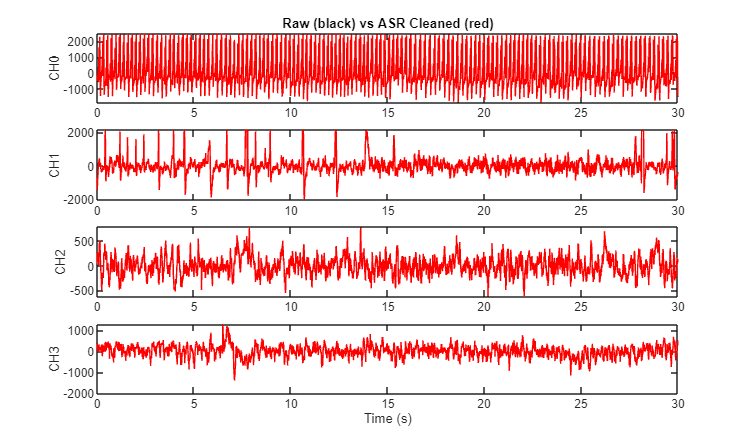

% validation plots
t = (0:N-1)/fs;
figure('Name','Time-domain: Raw vs Clean (first 30 s)','units','normalized','position',[0.05 0.05 0.9 0.85]);
plotDur = min(N, round(30*fs));
for ch=1:numCh
    subplot(numCh,1,ch);
    plot(t(1:plotDur), data(ch,1:plotDur), 'k'); hold on;
    plot(t(1:plotDur), clean(ch,1:plotDur), 'r'); hold off;
    ylabel(sprintf('CH%d', ch-1));
    if ch==1, title('Raw (black) vs ASR Cleaned (red)'); end
    if ch==numCh, xlabel('Time (s)'); end
end

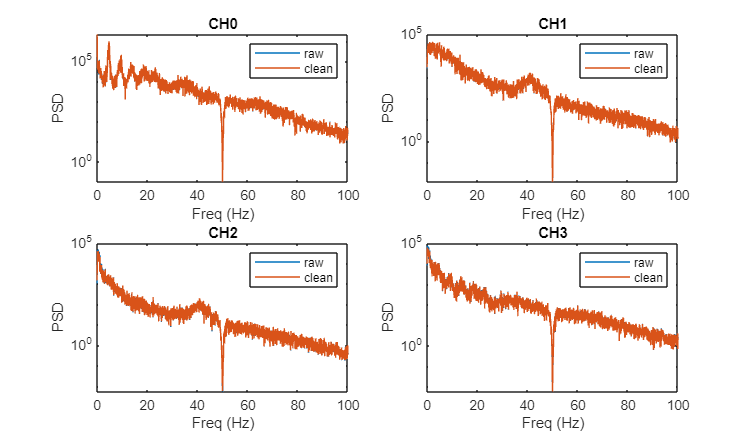

drawnow;
% PSD comparison (Welch)
figure('Name','PSD before vs after (Welch)','units','normalized','position',[0.05 0.05 0.9 0.85]);
for ch=1:numCh
    subplot(2,2,ch);
    [Praw,f] = pwelch(data(ch,:), [], [], [], fs);
    [Pclean,~] = pwelch(clean(ch,:), [], [], [], fs);
    semilogy(f, Praw); hold on;
    semilogy(f, Pclean); hold off;
    xlabel('Freq (Hz)'); ylabel('PSD');
    legend('raw','clean'); title(sprintf('CH%d', ch-1));
    xlim([0 min(100, fs/2)]);
end

drawnow;
CH0_ASR = clean(1, :);
CH1_ASR = clean(2, :);
CH2_ASR = clean(3, :);
CH3_ASR = clean(4, :);

Next we apply the ICA algorithm to remove eye blinks and other artifacts of the individual. For this I needed to use the FastICA package (downloaded and added to the same path of the files) 

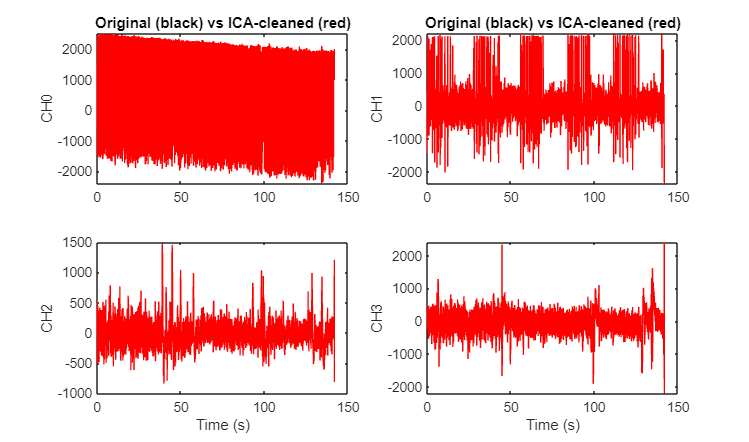

% use FastICA
addpath("C:\Users\Admin\Documents\JHU\FastICA_25"); % make sure FastICA is on your MATLAB path

% data matrix (channels x samples)
data_ica = [CH0_ASR; CH1_ASR; CH2_ASR; CH3_ASR];

% Run FastICA
[icasig, A, ~] = fastica(data_ica, 'approach','symm','g','tanh','verbose','off');


S = icasig;   % size: components x samples

% Identify components to remove (eye-blinks etc)
% For simplicity, we can zero-out obvious artifacts manually
S_cleaned = S; 

% Example: if component 1 and 3 are artifacts (just example)
% S_cleaned(1,:) = 0;
% S_cleaned(3,:) = 0;

% Reconstruct cleaned signals
data_cleaned = A * S_cleaned; % channels x samples

% Assign to neat channel variables
CH0_ICA = data_cleaned(1,:);
CH1_ICA = data_cleaned(2,:);
CH2_ICA = data_cleaned(3,:);
CH3_ICA = data_cleaned(4,:);

% Plot original vs ICA-cleaned channels (2 per column) ---
t = (0:length(CH0_ASR)-1)/fs;

figure('Name','Original vs ICA-cleaned','units','normalized','position',[0.05 0.05 0.9 0.85]);

channels = {CH0_ASR, CH1_ASR, CH2_ASR, CH3_ASR};
channels_ica = {CH0_ICA, CH1_ICA, CH2_ICA, CH3_ICA};

for ch = 1:4
    subplot(2,2,ch);
    plot(t, channels{ch}, 'k'); hold on;
    plot(t, channels_ica{ch}, 'r'); hold off;
    ylabel(sprintf('CH%d', ch-1));
    if ch <= 2
        title(sprintf('Original (black) vs ICA-cleaned (red)'));
    end
    if ch == 3 || ch ==4
        xlabel('Time (s)');
    end
end

drawnow;

Now we will plot the original DFTs vs the ICA-cleaned DFTs

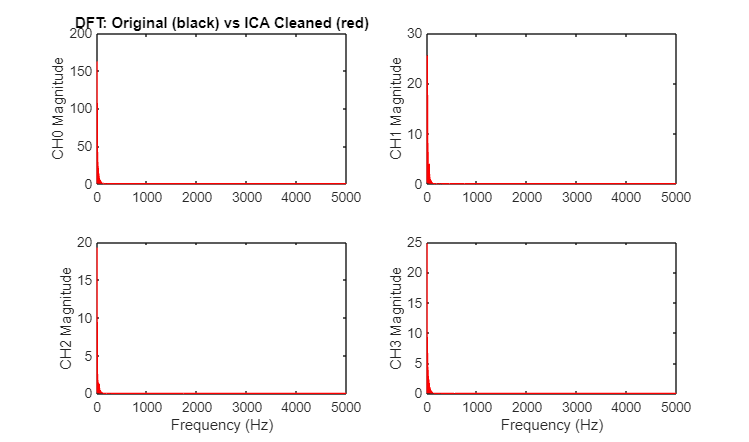

X_ICA_clean = A * S_cleaned;  % size: numCh x N

% Assign to individual variables for plotting
CH0_ICA_clean = X_ICA_clean(1,:);
CH1_ICA_clean = X_ICA_clean(2,:);
CH2_ICA_clean = X_ICA_clean(3,:);
CH3_ICA_clean = X_ICA_clean(4,:);
CH_orig = {CH0_ASR, CH1_ASR, CH2_ASR, CH3_ASR};
CH_clean = {CH0_ICA_clean, CH1_ICA_clean, CH2_ICA_clean, CH3_ICA_clean};
numCh = numel(CH_orig);
t = (0:length(CH0_ASR)-1)/fs;


% Frequency-domain (DFT) plots
figure('Name','Frequency Domain: Original vs ICA Cleaned','units','normalized','position',[0.05 0.05 0.9 0.85]);
for ch=1:numCh
    % compute DFTs
    N = length(CH_orig{ch});
    f = (0:N-1)*(fs/N);
    X_orig = abs(fft(CH_orig{ch}))/N;
    X_clean = abs(fft(CH_clean{ch}))/N;

    subplot(numCh/2, 2, ch);
    plot(f, X_orig, 'k'); hold on;
    plot(f, X_clean, 'r'); hold off;
    xlim([0 fs/2]); % plotting only up to Nyquist
    ylabel(sprintf('CH%d Magnitude', ch-1));
    if ch==1
        title('DFT: Original (black) vs ICA Cleaned (red)');
    end
    if ch>=numCh-1
        xlabel('Frequency (Hz)');
    end
end; drawnow; 

X_ASR = [CH0_ASR; CH1_ASR; CH2_ASR; CH3_ASR];  % ASR-cleaned signals


[icasig, A, W] = fastica(X_ASR, 'numOfIC', 4);

Number of signals: 4
Number of samples: 1418808
Calculating covariance...
Dimension not reduced.
Selected [ 4 ] dimensions.
Smallest remaining (non-zero) eigenvalue [ 32223.4 ]
Largest remaining (non-zero) eigenvalue [ 1.3526e+06 ]
Sum of removed eigenvalues [ 0 ]
[ 100 ] % of (non-zero) eigenvalues retained.
Whitening...
Check: covariance differs from identity by [ 2.9976e-15 ].
Used approach [ defl ].
Used nonlinearity [ pow3 ].
Starting ICA calculation...
IC 1 .................computed ( 17 steps ) 
IC 2 ........computed ( 8 steps ) 
IC 3 ........computed ( 8 steps ) 
IC 4 ..computed ( 2 steps ) 
Done.
Adding the mean back to the data.
